# Курс "Дискретные преобразования сигналов"

# Романюк Ю.А., Леус А.В., Тормагов Т.А.

# Лекция 2.

# 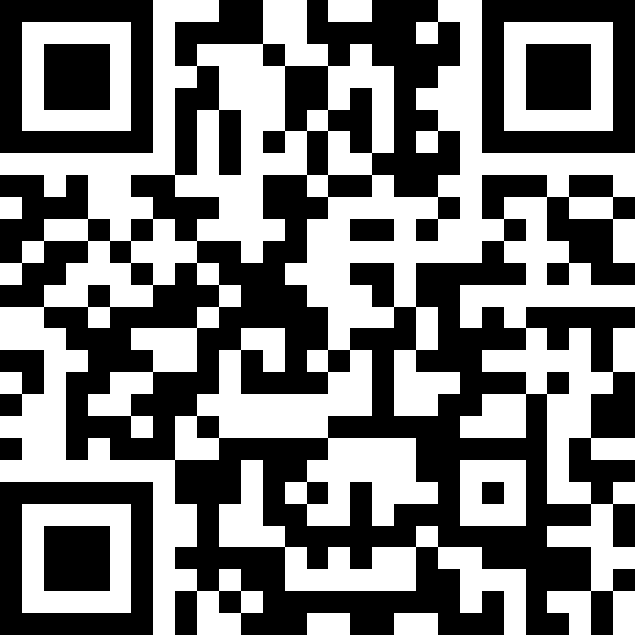

### Преобразование Фурье 

### Свойства преобразования Фурье

### Спектры импульсных и периодических сигналов

## Преобразование Фурье 

**Преобразование **[**Фурье**](https://ru.wikipedia.org/wiki/%D0%A4%D1%83%D1%80%D1%8C%D0%B5,_%D0%96%D0%B0%D0%BD_%D0%91%D0%B0%D1%82%D0%B8%D1%81%D1%82_%D0%96%D0%BE%D0%B7%D0%B5%D1%84) (символ **ℱ**) — операция, сопоставляющая одной [функции](https://ru.wikipedia.org/wiki/%D0%A4%D1%83%D0%BD%D0%BA%D1%86%D0%B8%D1%8F_(%D0%BC%D0%B0%D1%82%D0%B5%D0%BC%D0%B0%D1%82%D0%B8%D0%BA%D0%B0)) [вещественной переменной](https://ru.wikipedia.org/wiki/%D0%92%D0%B5%D1%89%D0%B5%D1%81%D1%82%D0%B2%D0%B5%D0%BD%D0%BD%D0%BE%D0%B5_%D1%87%D0%B8%D1%81%D0%BB%D0%BE) другую функцию вещественной переменной.

Все реальные сигналы имеют конечную удельную энергию:


$$\int_{-\infty }^{\infty } \left|x\left(t\right){\left|\right.}^2 \textrm{dt}\right.<\infty$$


Если $x\left(t\right)$- напряжение (или ток), действующее на единичном сопротивлении, то интеграл представляет энергию, выделяемую на единичном сопротивлении, и эта энергия конечна. В этом случае $x\left(t\right)$-функция с интегрируемым квадратом на всей оси. Таким образом, по теореме Планшереля для функции $x\left(t\right)$существует функция $X\left(f\right)$также с интегрируемым квадратом на всей оси, связанная с $x\left(t\right)$соотношением:


$$\lim_{T\to \infty } \int_{-T}^T {\left|X\left(f\right)-\int_{-T}^T x\left(t\right)e^{-j2\pi \textrm{ft}} \textrm{dt}\right|}^2 \textrm{df}=0\ldotp$$


Если функции $x\left(t\right)$и $X\left(f\right)$абсолютно интегрируемы, то 


$$\begin{array}{l}
F\left\lbrace x\left(t\right)\right\rbrace \left(f\right)=X\left(f\right)=\int_{-\infty }^{\infty } x\left(t\right)e^{-j2\pi \textrm{ft}} \textrm{dt},\\
x\left(t\right)=\int_{-\infty }^{\infty } X\left(f\right)e^{j2\pi \textrm{ft}} \textrm{df}\ldotp 
\end{array}$$


Эти соотношения определяют пару преобразований Фурье (ПФ) - соответственно прямое и обратное.

Для частоты $\omega =2\pi f$ пара ПФ имеет вид:


$$\begin{array}{l}
X\left(\omega \right)=\int_{-\infty }^{\infty } x\left(t\right)e^{-j\omega t} \textrm{dt},\\
x\left(t\right)=\frac{1}{2\pi }\int_{-\infty }^{\infty } X\left(\omega \right)e^{j\omega t} d\omega \ldotp 
\end{array}$$


Первый интеграл называется спектральной плотностью, а второй - интегралом Фурье. Далее по тексту ПФ может обозначаться символом $\prime \leftrightarrow$'.

## Свойства преобразования Фурье

1. Свойство линейности: 


$$\begin{array}{l}
F\left\lbrace x_1 \left(t\right)+x_2 \left(t\right)\right\rbrace \left(f\right)=X_1 \left(f\right)+X_2 \left(f\right);\\
x_1 \left(t\right)+x_2 \left(t\right)\leftrightarrow X_1 \left(f\right)+X_2 \left(f\right)
\end{array}$$


2. Теорема запаздывания: 


$$F\left\lbrace x\left(t-\tau \right)\right\rbrace \left(f\right)=e^{-\textrm{j2}\pi f\tau } X\left(f\right);$$


3. Теорема смещения: 


$$F\left\lbrace x\left(t\right)e^{-\textrm{j2}\pi f_0 t} \right\rbrace \left(f\right)=X\left(f+f_0 \right);$$


4. Теорема Парсеваля-Релея:


$$\int_{-\infty }^{\infty } x_1 \left(t\right)x_2^* \left(t\right)\textrm{dt}=\int_{-\infty }^{\infty } X_1 \left(f\right)X_2^* \left(f\right)\textrm{df};$$


5. Теорема о спектре произведения:


$$F\left\lbrace x_1 \left(t\right)\cdot x_2 \left(t\right)\right\rbrace \left(f\right)=X_1 \left(f\right)\otimes X_2 \left(f\right)=\int_{-\infty }^{\infty } X_1 \left(\nu \right)X_2 \left(f-\nu \right)d\nu ;$$


6. Теорема о спектре свертки:


$$F\left\lbrace x_1 \left(t\right)\otimes x_2 \left(t\right)\right\rbrace \left(f\right)=\int_{-\infty }^{\infty } {\int_{-\infty }^{\infty } x_1 \left(\tau \right)x_2 \left(t-\tau \right)d\tau \;e^{-j2\pi \textrm{ft}} \textrm{dt}}_1 =X_1 \left(f\right)\cdot X_2 \left(f\right);$$


7. Теорема об изменении масштаба:


$$F\left\lbrace x\left(a\cdot t\right)\right\rbrace \left(f\right)=\frac{1}{a}X\left(\frac{f}{a}\right);$$


8. Теорема о спектре производной:


$$F\left\lbrace \frac{\textrm{dx}\left(t\right)}{\textrm{dt}}\right\rbrace \left(f\right)=\textrm{j2}\pi \textrm{fX}\left(f\right);$$


9. Теорема о производной спектра:


$$F\left\lbrace t\cdot x\left(t\right)\right\rbrace \left(f\right)=\frac{1}{\textrm{j2}\pi }\frac{\textrm{dX}\left(f\right)}{\textrm{df}}\ldotp$$


## Спектры импульсных и периодических сигналов

### Дельта-функция. Спектр $\delta$-функции.

Введём в рассмотрение дельта-функции Дирака. Их корректное определение даётся в теории обобщённых функций. Здесь мы воспользуемся некоторыми полезными свойствами этих функций. 

*Дельта-функция Дирака* по определению равна бесконечности, когда её аргумент равен нулю, и нулю – при остальных значениях, причём площадь под её графиком равна единице. Таким образом,

$\delta \left(t-t_0 \right)=\left\lbrace \begin{array}{cc}
\infty  & \textrm{при}\;\;t=t_0 \\
0 & \textrm{при}\;t\not= t_0 
\end{array}\right.$   и $\int_{t_0 -\varepsilon }^{t_0 +\varepsilon } \delta \left(t-t_0 \right)\textrm{dt}=1$ при любом $\varepsilon >0\ldotp$

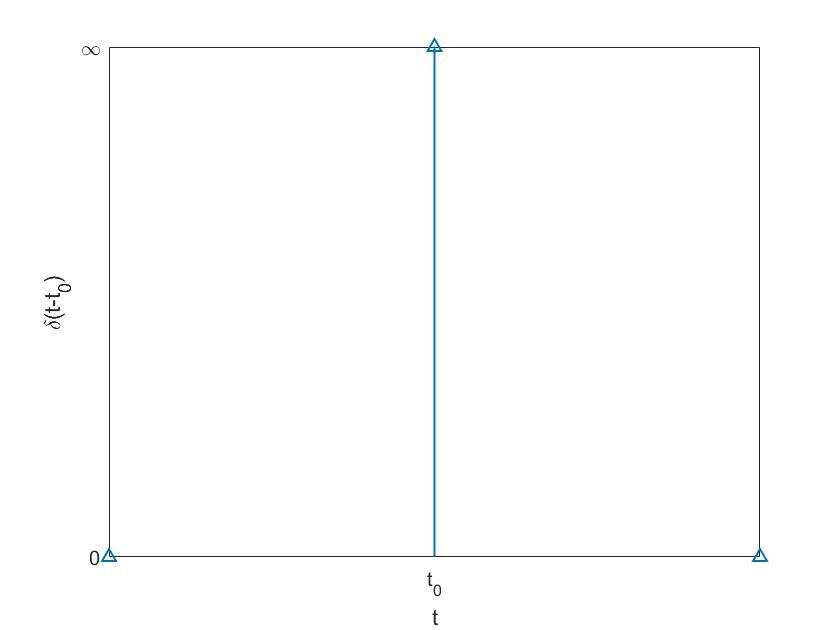

Часто желательно определять эту функцию так, чтобы она была четной функцией своего аргумента:

$\delta \left(t-t_0 \right)=\delta \left(t_0 -t\right)$ в этом случае $\int_{t_0 -\varepsilon }^{t_0 } \delta \left(t-t_0 \right)\textrm{dt}=\int_{t_0 }^{t_0 +\varepsilon } \delta \left(t-t_0 \right)\textrm{dt}=\frac{1}{2},\;\varepsilon >0\ldotp$

Предположим, что дельта-функция интегрируема по интервалу $\left(-\infty ;t\right)\ldotp$ Тогда 

$\int_{-\infty }^t \delta \left(\tau -t_0 \right)d\tau =\sigma \left({t-\;t}_0 \right),$ где $\sigma \left({t-\;t}_0 \right)$ - функция единичного скачка или функция Хэвисайда:

 $\sigma \left({t-\;t}_0 \right)=\left\lbrace \begin{array}{cc}
1 & \textrm{при}\;\;t>t_0 ,\\
\frac{1}{2} & \textrm{при}\;t=t_0 ,\\
0 & \textrm{при}\;t<t_0 \ldotp 
\end{array}\right.$ Таким образом, функция единичного скачка является интегралом от дельта-функции. Следовательно:


$$\sigma {\;}^{\prime } \left(t-t_0 \right)=\delta \left(t-t_0 \right)\;\ldotp$$


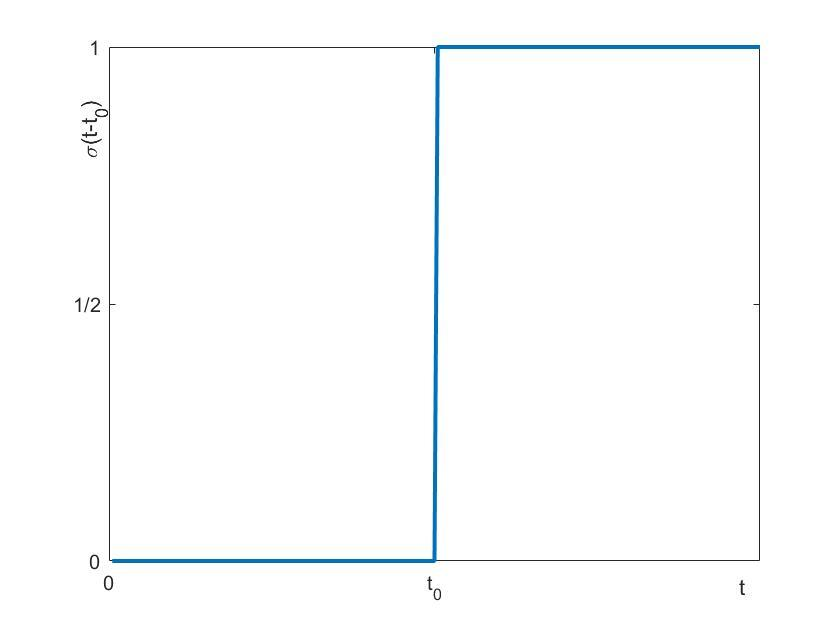

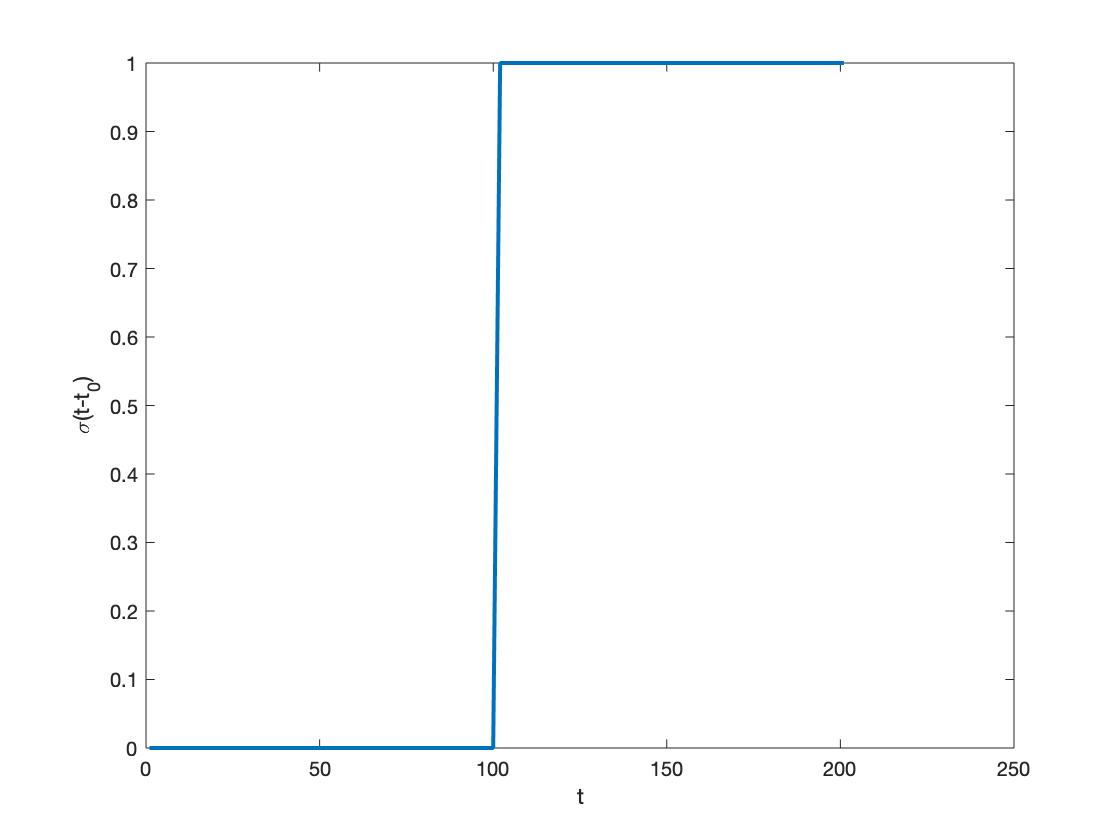

x=[zeros(1, 100) 0.5 ones(1, 100)];
figure; plot(x, 'LineWidth', 2); 
xlabel('t'); ylabel('\sigma(t-t_0)');

Известно так называемое фильтрующее свойство дельта-функции, заключающееся в том, что ее свертка с любой ограниченной и непрерывной в точке $t_0$ функцией $x\left(t\right)$равна


$$\int_a^b x\left(t\right)\delta \left(t-t_0 \right)\textrm{dt}=\left\lbrace \begin{array}{cc}
x\left(t_0 \right) & a<t_0 <b,\\
\frac{1}{2}x\left(t_0 \right) & t_0 =a\;\textrm{или}\;t_0 =b,\\
0 & t_0 <a\;\textrm{или}\;t_0 >b\ldotp 
\end{array}\right.\;$$


Если функция $x\left(t\right)$ в точке $t=t_0 ,\;\;\left(t_0 \in \left(a,b\right)\right)$ имеет разрыв первого рода, то 

$\int_a^b x\left(t\right)\delta \left(t-t_0 \right)\textrm{dt}=\frac{1}{2}\cdot \left(x\left(t_{0+} \right)+x\left(t_{0-} \right)\right)\;$, 

где $x\left(t_{0+} \right)$и $x\left(t_{0-} \right)$ - значения $x\left(t\right)$соответственно справа и слева от точки разрыва.

Если $t_0$ - действительная величина, то выполняется следующее равенство:


$$\int_{-\infty \;\;}^{\infty \;} x\left(t\right)\delta \left(t-t_0 \right)\textrm{dt}=x\left(t_0 \right)\ldotp \;$$


Пусть $x\left(t\right)=e^{-\textrm{j2}\pi \textrm{ft}}$, тогда


$$\int_{-\infty \;}^{\infty \;} \delta \left(t\right)e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}=e^0 =1\ldotp$$



$$F\left\lbrace \delta \left(t-t_0 \right)\right\rbrace \left(f\right)=\int_{-\infty }^{\infty } \delta \left(t-t_0 \right)\cdot e^{-j2\pi \textrm{ft}} \textrm{dt}=e^{-\textrm{j2}\pi {\textrm{ft}}_0 } \ldotp \;$$


Отсюда следует еще одно полезное соотношение (обратное преобразование Фурье):


$$\delta \left(t\right)=\int_{-\infty \;}^{\infty \;} e^{\textrm{j2}\pi \textrm{ft}} \textrm{df}\;=\int_{-\infty \;}^{\infty \;} e^{-\textrm{j2}\pi \textrm{ft}} \textrm{df}\;,\;\;\Rightarrow \;\;\int_{-\infty }^{\infty } e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}=\delta \left(f\right)\ldotp \;$$


Тогда преобразование Фурье функции $x\left(t\right)=e^{\textrm{j2}\pi f_0 t}$ :

 
$$F\left\lbrace e^{\textrm{j2}\pi f_0 t} \right\rbrace \left(f\right)=\int_{-\infty }^{\infty } e^{\textrm{j2}\pi f_0 t} e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}=\int_{-\infty }^{\infty } e^{-\textrm{j2}\pi t\left(f-f_0 \right)} \textrm{dt}=\delta \left(f-f_0 \right)\ldotp$$


Итак, необходимо помнить следующие формулы для преобразования Фурье (обозначается $\prime \leftrightarrow^{\prime }$):


$$\begin{array}{l}
F\left\lbrace \delta \left(t\right)\right\rbrace \left(f\right)=1,\;\;\Leftrightarrow \;\delta \left(t\right)\leftrightarrow 1;\\
F\left\lbrace \delta \left(t-t_0 \right)\right\rbrace \left(f\right)=e^{-\textrm{j2}\pi {\textrm{ft}}_0 } ,\;\;\Leftrightarrow \;\delta \left(t-t_0 \right)\leftrightarrow e^{-\textrm{j2}\pi {\textrm{ft}}_0 } ,\\
F\left\lbrace e^{\textrm{j2}\pi f_0 t} \right\rbrace \left(f\right)=\delta \left(f-f_0 \right),\;\;\Leftrightarrow \;\;e^{\textrm{j2}\pi f_0 t} \leftrightarrow \delta \left(f-f_0 \right)\ldotp 
\end{array}$$


#### Спектр гармонического сигнала

Рассмотрим функцию $x\left(t\right)=e^{\textrm{j2}\pi f_0 t}$, где $t\in \left(-\infty ;+\infty \right)$, представляющей в комплексной форме гармонический сигнал с частотой $f_0$. Используя приведенные выше соотношения для дельта-функции, можем записать:

$\;\;e^{\textrm{j2}\pi f_0 t} \leftrightarrow \delta \left(f-f_0 \right)$. Это важное соотношение мы используем для получения спектральной функции периодического сигнала.

Для действительного гармонического сигнала $\cos \left(2\pi f_0 t\right)$с учетом Формулы Эйлера $\left(\cos \left(2\pi f_0 t\right)=\frac{e^{\textrm{j2}\pi f_0 t} +e^{-\textrm{j2}\pi f_0 t} }{2}\right)$


$$\begin{array}{l}
F\left\lbrace \cos \left(2\pi f_0 t\right)\right\rbrace =\int_{-\infty }^{\infty } \cos \left(2\pi f_0 t\right)e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}=\int_{-\infty }^{\infty } \frac{e^{\textrm{j2}\pi f_0 t} +e^{-\textrm{j2}\pi f_0 t} }{2}{\;e}^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}=\\
=\frac{1}{2}\left(\int_{-\infty }^{\infty } e^{j2\pi f_0 t} e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}+\int_{-\infty }^{\infty } e^{-\textrm{j2}\pi f_0 t} e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}\right)=\frac{1}{2}\left(\delta \left(f-f_0 \right)+\delta \left(f+f_0 \right)\right)\ldotp 
\end{array}$$


 По аналогии для гармонического сигнала $\sin \left(2\pi f_0 t\right)$:

$F\left\lbrace \sin \left(2\pi f_0 t\right)\right\rbrace =$$\frac{1}{2j}\left(\delta \left(f-f_0 \right)-\delta \left(f+f_0 \right)\right)$.

Итак, спектры гармонических сигналов имеют следующий вид:


$$\begin{array}{l}
\cos \left(2\pi f_0 t\right)\leftrightarrow \frac{1}{2}\left(\delta \left(f-f_0 \right)+\delta \left(f+f_0 \right)\right),\\
\sin \left(2\pi f_0 t\right)\leftrightarrow \frac{1}{2j}\left(\delta \left(f-f_0 \right)-\delta \left(f+f_0 \right)\right)\ldotp \;
\end{array}$$


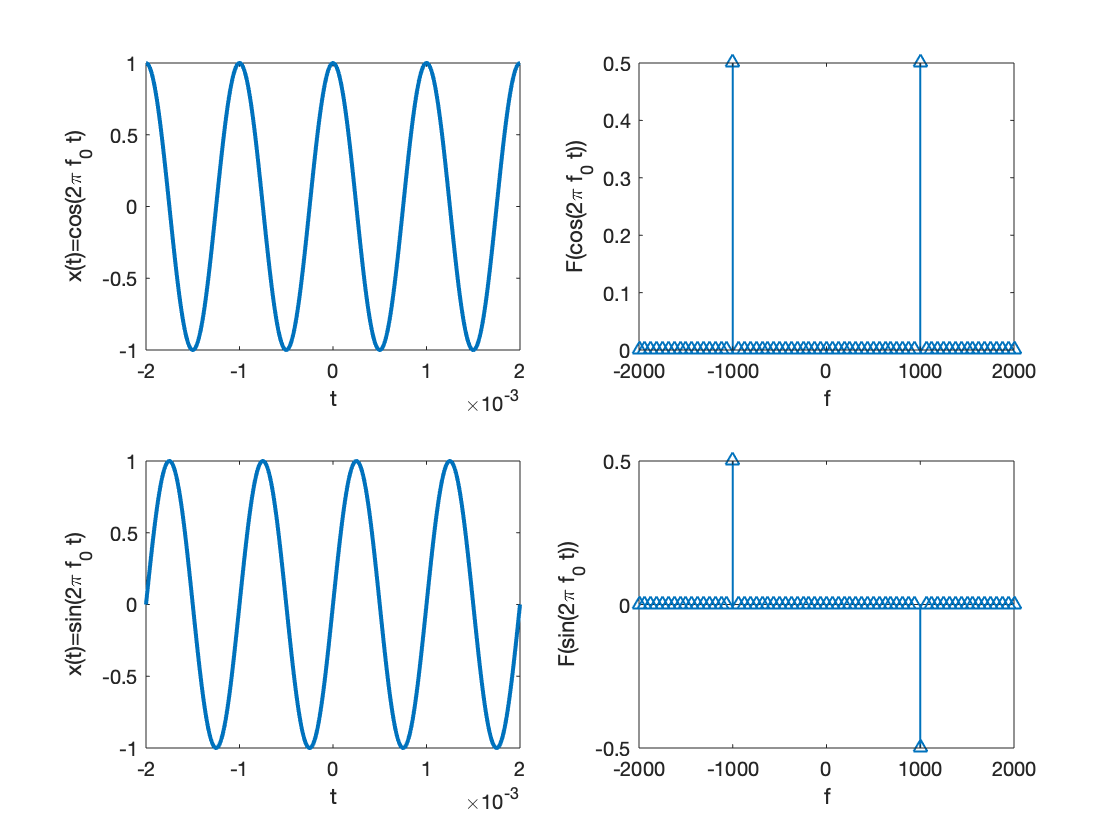

f0=1*10^3;   % частота синусоиды/косинусоиды 1кГц
T=2/f0; % период синусоиды/косинусоиды
f=linspace(-2*f0, 2*f0, 65);
t=linspace(-T, T, 500); % моделируем временной интервал, равный 4м периодам

xcos = cos(2*pi*f0*t);
fcos = 0.5*(dirac(f-f0)+dirac(f+f0));
idx = fcos == inf; fcos(idx) = 0.5;

xsin = sin(2*pi*f0*t);
fsin = 0.5*(dirac(f-f0)-dirac(f+f0))/1i;
fsin = imag(fsin);
idx = fsin == inf; fsin(idx) = 0.5;
idx = fsin == -inf; fsin(idx) = -0.5;


% Строим графики
figure;
subplot(2,2,1); plot(t,xcos,'LineWidth',2); 
xlabel('t'); ylabel('x(t)=cos(2\pi f_0 t)');
subplot(2,2,2); stem(f,fcos, 'LineWidth', 1, 'Marker', '^');
xlabel('f'); ylabel('F(cos(2\pi f_0 t))');
subplot(2,2,3); plot(t,xsin,'LineWidth',2);
xlabel('t'); ylabel('x(t)=sin(2\pi f_0 t)');
subplot(2,2,4); stem(f, fsin, 'LineWidth', 1, 'Marker', '^');
xlabel('f'); ylabel('F(sin(2\pi f_0 t))');

#### Спектр T-периодического сигнала

Рассмотрим некоторый сигнал $x\left(t\right)$, передающийся с периодом $T$.

Такой сигнал может быть представлен своим рядом Фурье:


$$x\left(t\right)=\sum_{n=-\infty }^{\infty } A_n e^{j\frac{2\pi }{T}\textrm{nt}}$$


где по определению

 
$$A_n =\frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} x\left(t\right)e^{-j\frac{2\pi }{T}\textrm{nt}} \textrm{dt}\ldotp$$


$\Delta f=\frac{1}{T}$  - расстояние между гармониками в спектре T-периодического сигнала. Предполагается, что функция $x\left(t\right)$ удовлетворяет условиям Дирихле (непрерывная или имеет конечное число разрывов на интервале $\left\lbrack -\frac{T}{2},\frac{T}{2}\right\rbrack ,$ и число максимумов и минимумов на этом интервале конечно.

Чтобы получить спектральную функцию Т-периодического сигнала, воспользуемся приведенным выше выражением для спектра комплексного гармонического сигнала. Тогда


$$F\left\lbrace x\left(t\right)\right\rbrace =\int_{-\infty }^{\infty } \sum_{n=-\infty }^{\infty } A_n e^{j\frac{2\pi }{T}\textrm{nt}} e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}=\sum_{n=-\infty }^{\infty } A_n \int_{-\infty }^{\infty } e^{\textrm{j2}\pi \Delta f\cdot \textrm{nt}} e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}=\sum_{n=-\infty }^{\infty } A_n \delta \left(f-n\Delta f\right)\ldotp$$


Таким образом, спектральная функция Т-периодического сигнала имеет дискретную структуру в виде взвешенной последовательности $\delta$-функций. Площади отдельных $\delta$-функций равны соответствующим коэффициентам ряда Фурье, а период следования на частотной оси $\Delta f=\frac{1}{T}$ . Такое представление спектра периодического сигнала является удобной математической идеализацией, как, впрочем, идеализацией является и сам периодический сигнал.

Размерность дискретного амплитудного спектра $A_n$ имеет размерность самого сигнала, в то время как спектральная функция $X\left(f\right)$ непериодического сигнала имеет размерность самого сигнала, умноженную на размерность времени.

#### Спектр периодической последовательности $\delta -$функций.

Рассмотрим последовательность $\delta \;$-функций (с периодом $T$):

$D\left(t\right)=\sum_{k=-\infty }^{\infty } \delta \left(t-k\cdot T\right)\ldotp$ Эту последовательность иногда называют *гребенкой Дирака*. Ряд Фурье такой $T$-периодической последовательности $\delta$-функций:


$$D\left(t\right)=\sum_{n=-\infty }^{\infty } C_n e^{j\frac{2\pi }{T}\textrm{nt}}$$


где $C_n$- коэффициенты Фурье $\delta \;$- функции (на одном периоде расположена одна такая функция). Вычислим эти коэффициенты:


$$C_n =\frac{1}{T}\int_{-\frac{T}{2}}^{\frac{T}{2}} \delta \left(t\right)e^{-j\frac{2\pi }{T}\textrm{nt}} \textrm{dt}=\frac{1}{T}e^0 =\frac{1}{T},\;\;\;\;\;\;\forall n\ldotp \;\;\;$$


Таким образом, независимо от $n$ коэффициенты ряда Фурье равны $\frac{1}{T}$:


$$D\left(t\right)=\frac{1}{T}\sum_{n=-\infty }^{\infty } e^{-j\frac{2\pi }{T}\textrm{nt}} \ldotp$$


Вычислим преобразование Фурье для данной последовательности


$$\begin{array}{l}
F\left\lbrace D\left(t\right)\right\rbrace =\int_{-\infty }^{\infty } D\left(t\right)e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}=\int_{-\infty }^{\infty } \frac{1}{T}\sum_{n=-\infty }^{\infty } e^{j\frac{2\pi }{T}\textrm{nt}} e^{-\textrm{j2}\pi \textrm{ft}} \textrm{dt}=\frac{1}{T}\sum_{n=-\infty }^{\infty } \int_{-\infty }^{\infty } e^{-2\pi t\left(f-n\Delta f\right)} \textrm{dt}=\\
=\frac{1}{T}\sum_{n=-\infty }^{\infty } \delta \left(f-n\Delta f\right)=\Delta f\sum_{n=-\infty }^{\infty } \delta \left(f-n\Delta f\right)\ldotp 
\end{array}$$


Таким образом, преобразование Фурье для гребенки Дирака во временной области является гребенка Дирака в частотной области:


$$\sum_{k=-\infty }^{\infty } \delta \left(t-k\cdot T\right)\;\leftrightarrow \Delta f\sum_{n=-\infty }^{\infty } \delta \left(f-n\Delta f\right)\ldotp \;$$
  

Соответствие $D_T \left(t\right)\leftrightarrow D_{\Delta f} \left(f\right)$ называется *формулой Пуассона *и ниже будет проиллюстрировано на графиках. Площади отдельных $\delta$-импульсов равны 1 в частотной области и равны $\Delta f$ в частотной области.

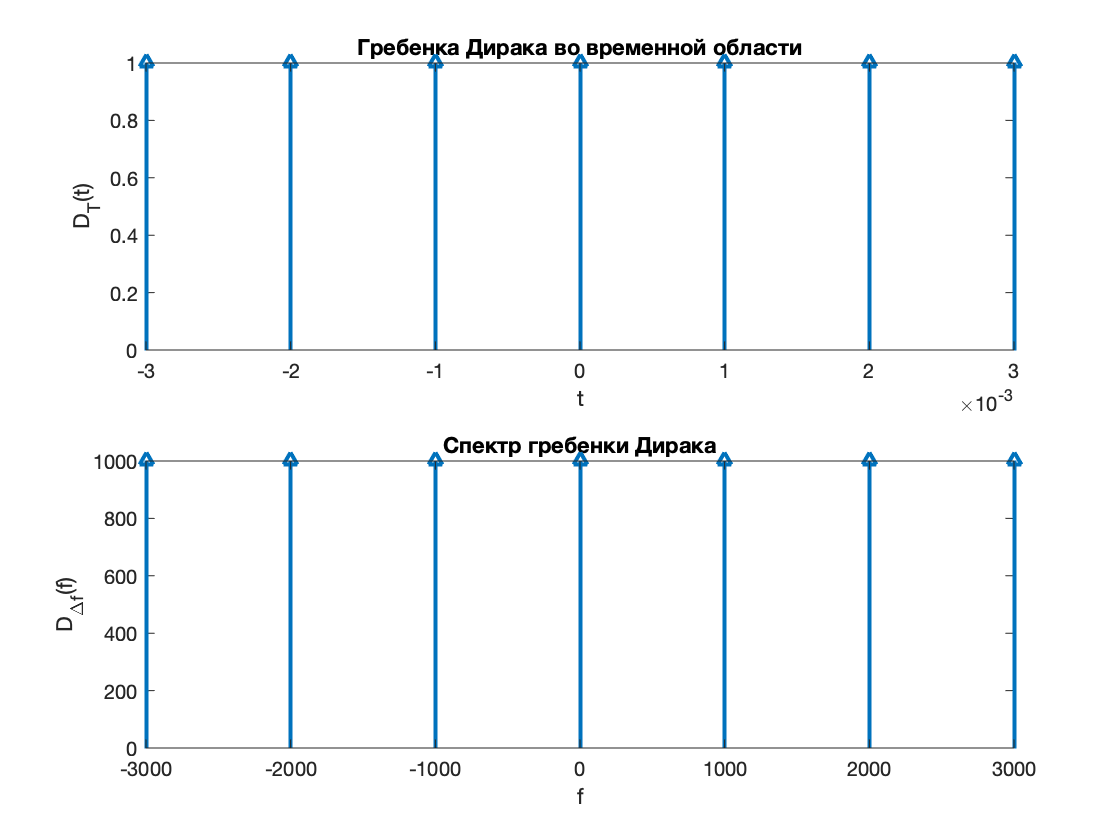

f0=1*10^3;      % частота дельта-функций
T=1/f0;         % период дельта-функций
f=linspace(-3*f0, 3*f0, 7);
t=linspace(-3*T, 3*T, 7); % моделируем временной интервал, равный 4м периодам
Dt=ones(1,numel(t));
Df=ones(1,numel(f))*f0;
% Строим графики
figure;
subplot(2,1,1); stem(t, Dt,'LineWidth',2,'Marker', '^'); 
xlabel('t'); ylabel('D_T(t)'); title('Гребенка Дирака во временной области');
subplot(2,1,2); stem(f,Df, 'LineWidth', 2, 'Marker', '^');
xlabel('f'); ylabel('D_\Delta_f(f)'); title('Спектр гребенки Дирака');

#### Спектр произвольного периодического сигнала.

Рассмотрим некий периодический сигнал $x\left(t\right)$ с периодом $T$.  Выделим один период данного сигнала $\to \left\lbrace \begin{array}{cc}
x_T \left(t\right)=x\left(t\right) & t\in \left\lbrack 0,T\right\rbrack ,\\
x_T \left(t\right)=0 & t\not\in \left\lbrack 0,T\right\rbrack \ldotp 
\end{array}\right.$ Тогда сигнал x(t) может быть представлен в виде свертки: $x\left(t\right)=x_T \left(t\right)\otimes D_T \left(t\right)\ldotp$

В спектральной области свертке соответствует произведение Фурье-образов


$$F\left\lbrace x\left(t\right)\right\rbrace =F\left\lbrace x_T \left(t\right)\right\rbrace \cdot F\left\lbrace D_T \left(t\right)\right\rbrace =X_T \left(f\right)\cdot D_{\Delta f} \left(f\right)=X_T \left(f\right)\cdot \Delta f\sum_{n=-\infty }^{\infty } \delta \left(f-n\Delta f\right)\ldotp$$


где $X_T \left(f\right)$- спектральная функция, соответствующая одному периоду сигнала.

Таким образом, получаем, что спектр периодического сигнала (период $T$) представляет собой последовательность $\delta$-функций с периодом $\Delta f=\frac{1}{T}$, умноженную на спектр одного периода данного сигнала (значение площади каждой $\delta$-функции будет равно значению спектра одного периода в соответствующей точке).

#### Спектр периодической последовательности прямоугольных импульсов.

В качестве примера возьмем прямоугольный импульс и повторим его с периодом $T$. 

Спектр одиночного прямоугольного импульса:

 
$$X_T \left(f\right)=\int_{-\frac{T}{2}}^{\frac{T}{2}} E\cdot e^{-j2\pi \textrm{ft}} \textrm{dt}=-\frac{E}{2\pi f}\cdot e^{-j2\pi \textrm{ft}} {\left|\right.}_{-\frac{T}{2}}^{\frac{T}{2}} =-\frac{E}{j2\pi f}\left(e^{-j\frac{2\pi \textrm{fT}}{2}} -e^{j\frac{2\pi \textrm{fT}}{2}} \right)=\frac{E}{\pi f}\sin \left(\pi f\;T\right)=E\;T\frac{\sin \left(\pi fT\right)}{\pi fT}\ldotp$$


При этом спектр периодической последовательности прямоугольных импульсов будет равен:


$$X\left(f\right)=E\;T\frac{\sin \left(\pi fT\right)}{\pi fT}\Delta f\sum_{n=-\infty }^{\infty } \delta \left(f-n\Delta f\right)\ldotp$$


Построим соответствующий график:

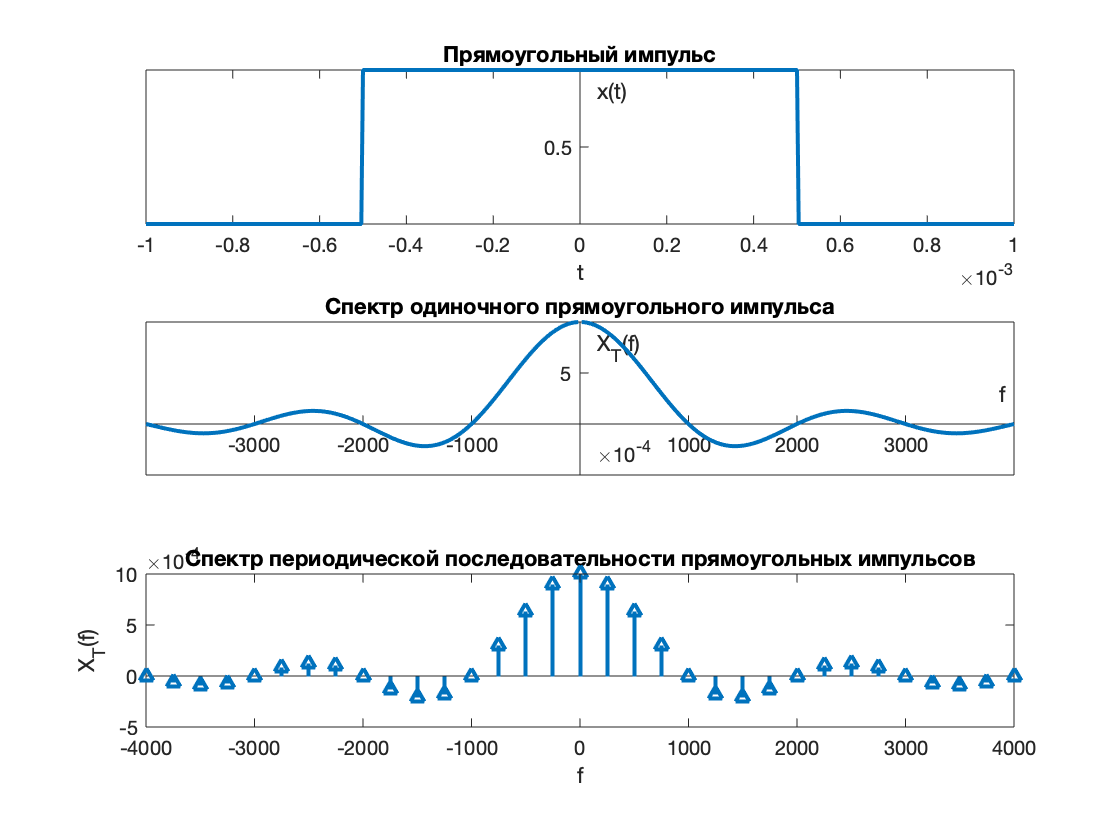

f0=1*10^3;      
T=1/f0;         
f=linspace(-4*f0, 4*f0, 513);
df=min(f):(f0/4):max(f); % период, последовательности прямоугольных импульсов равен 3м длинам импульса
t=linspace(-T, T, 513); 
xt=[zeros(1,(numel(t)-1)/4), ones(1,((numel(t))-1)/2+1), zeros(1,(numel(t)-1)/4)];
XTf=sin(pi*T*f)./(pi*f);
Xf=sin(pi*T*df)./(pi*df);
Xf(fix(numel(df)/2)+1)=T;
% Строим графики
figure;
subplot1 = subplot(3,1,1); plot(t, xt,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Прямоугольный импульс');
subplot2 = subplot(3,1,2); plot(f, XTf, 'LineWidth', 2);
set(subplot2,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('f'); ylabel('X_T(f)'); title('Спектр одиночного прямоугольного импульса');
subplot3 = subplot(3,1,3); stem(df, Xf, 'LineWidth', 2, 'Marker', '^');
set(subplot2,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('f'); ylabel('X_T(f)'); 
title('Спектр периодической последовательности прямоугольных импульсов');

### Реализации дельта-функции.

Прямоугольный импульс $П_{\tau \;} \left(t\right)$ длительностью $\tau \;$.

f0=1*10^3;
T=1/f0;
tau=T/100;
E = 1/tau;
t=linspace(-T, T, 2049);
for k=1:numel(t)
    if abs(t(k))<tau Rect(k)=E;
    else Rect(k)=0;
    end
end
figure;
subplot1 = subplot(3,1,1); plot(t, Rect,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Аппроксимация \delta -функции');

Функция $g\left(t\right)=\frac{1}{\sqrt{\left(2\pi \right)\;}\tau \;}e^{\left(-\frac{t^2 }{2\tau^2 }\right)} \;$

gt=1/(((2*pi)^0.5)*tau)*exp(-t.*t/(2*tau^2));
subplot1 = subplot(3,1,2); plot(t, gt,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Аппроксимация \delta -функции');

Функция $s\left(t\right)=\frac{\;\sin \frac{\pi t}{\tau \;}}{\pi t}$

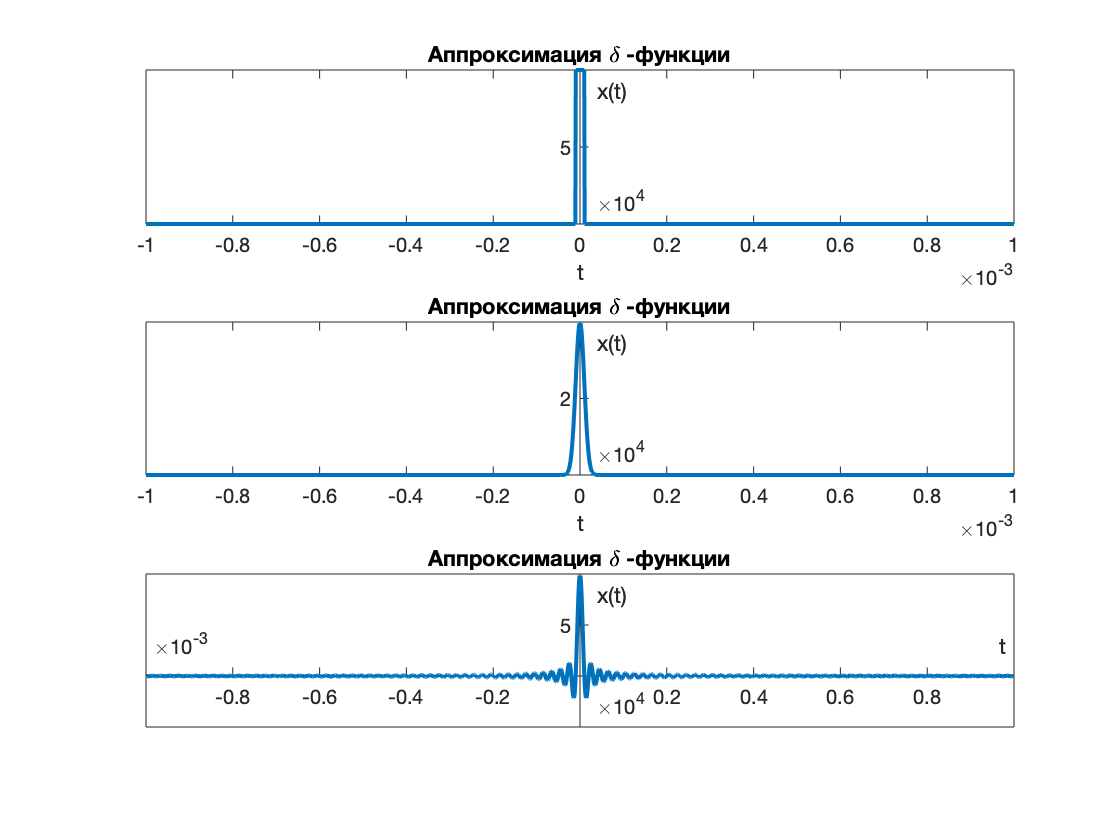

st=sin(pi*t/tau)./(pi*t);
subplot1 = subplot(3,1,3); plot(t, st,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Аппроксимация \delta -функции');

Задачи для самостоятельного решения:

- Изобразить на одном графике (в среде Matlab или Python на выбор) модули спектров двух последовательностей с одинаковым периодом T: